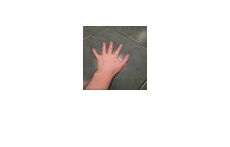

clear all; close all;
warning('off')
reka = imread("reka.ppm");
imshow(reka)

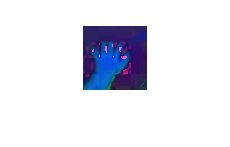

after = rgb2hsv(reka);
imshow(after)

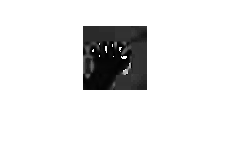

imshow(after(:,:,1))

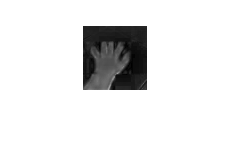

imshow(after(:,:,2))

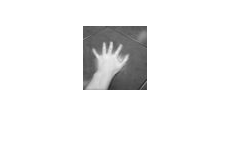

imshow(after(:,:,3))

z = 1;
c = 8;
u = 0;
word = 1 + c + u;

R = reka(:,:,1)

R = 64×64 uint8 matrix
    90    90    89    85    81    81    87    94    89    89    91    93    96    98    98    98   104   100    98   102   106   102    89    76    81    85    90    95    96    94    91    88    97    95    92    90    96   102    99    92    90    93    93    89    89    92    91    88    88    84
    94    93    92    91    90    92    94    96    95    94    94    95    98   100   101   102   103   101    99    98    98    96    91    87    97    95    93    91    90    91    91    92    86    93    98   101   102   102    95    87    89    92    92    90    90    94    94    91    88    84
    96    94    93    94    97    98    97    96    94    94    93    94    95    97    99   100    96    98    98    95    92    93    98   103   109   106   101    95    92    92    92    93    95    99   102   100    97    97    96    95    91    93    93    92    93    95    95    94    88    85
    93    92    92    92    93    94    94    93    92    93    95    95  

%R = 200;
R = R / 255;
R_FIX = fi(R,1,word,u,'RoundingMethod','Floor')

R_FIX =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


G = reka(:,:,2);
%G = 140;
G = G / 255;
G_FIX = fi(G,1,word,u,'RoundingMethod','Floor');

B = reka(:,:,3);
%B = 50;
B = B / 255;
B_FIX = fi(B,1,word,u,'RoundingMethod','Floor');

%aft = rgb2hsv(R,G,B)

s = size(R_FIX)

s =     64    64


row = s(1);
column = s(2);

for i=1:row
    for j=1:column
        M_FIX(i,j) = max(max(R_FIX(i,j),G_FIX(i,j)),B_FIX(i,j));
        min_FIX(i,j) = min(min(R_FIX(i,j),G_FIX(i,j)),B_FIX(i,j));
    end
end

M_FIX

M_FIX =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

% V
V_255 = floor(double(M_FIX)*255)

V_255 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

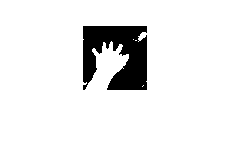

imshow(V_255)

% S
for i=1:row
    for j=1:column
        if M_FIX(i,j) == 0
            S(i,j) = 0;
        else
            S(i,j) = (M_FIX(i,j)- min_FIX(i,j)) / M_FIX(i,j);
        end
    end
end

S_255 = floor(double(S)*255)

S_255 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

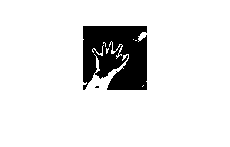

imshow(S_255)

% H

sixty = fi(60,1,word,u,'RoundingMethod','Floor');

for i=1:row
    for j=1:column
        %if  M_FIX(i,j) - min_FIX(i,j) == 0
            %H(i,j) = 0;
        if M_FIX(i,j) == R_FIX(i,j)
            new = (G_FIX(i,j) - B_FIX(i,j))  / (M_FIX(i,j)- min_FIX(i,j));
            H(i,j) = sixty*fi(new,1,word,u,'RoundingMethod','Floor');
            
        elseif M_FIX(i,j) == G_FIX(i,j)
            new = (B_FIX(i,j) - R_FIX(i,j))  / (M_FIX(i,j)- min_FIX(i,j));
            H(i,j) = sixty*fi(new,1,word,u,'RoundingMethod','Floor')+120;
             
        elseif M_FIX(i,j) == B_FIX(i,j)
            new = (R_FIX(i,j) - G_FIX(i,j))  / (M_FIX(i,j)- min_FIX(i,j));
            H(i,j) = sixty* fi(new,1,word,u,'RoundingMethod','Floor') + 240;
        end
        
        if H(i,j) < 0
            H(i,j) = H(i,j) + 360; 
        end  

        H(i,j) = fi(H(i,j)/360,1,word,u,'RoundingMethod','Floor');
    end
end

H_255 = floor(double(H)/42*255);

HSV(:,:,1) = H_255

HSV =    255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255 

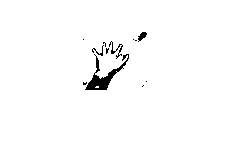

imshow(H_255)

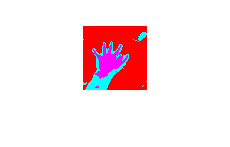

HSV(:,:,1) = H_255;
HSV(:,:,2) = S_255;
HSV(:,:,3) = V_255;

imshow(HSV)